% sets font variables

set(0, 'defaultAxesFontSize', 14)

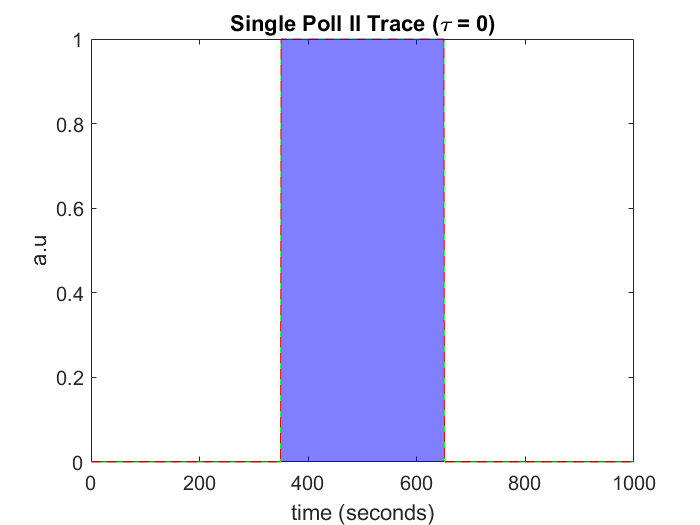

% creates single polymerase trace

elong_time = 300;
poll_start = 350;
total_len = 1000;

fig1 = zeros(1,total_len);
fig1(1,poll_start:poll_start + elong_time) = 1;

delay0 = fig1;
delay_half = zeros(1, total_len);
delay_half(1, (poll_start + elong_time / 2):(poll_start + 3 * elong_time / 2)) = 1;

delay_full = zeros(1, total_len);
delay_full(1, poll_start + elong_time:poll_start + 2*elong_time) = 1;

corr = zeros(1, total_len);
corr(1:elong_time + 1) = (elong_time - (0:elong_time)) / elong_time;

figure();
plot(1:total_len, fig1, 'g')
hold on
plot(1:total_len, delay0, '--r')
title('Single Poll II Trace (\tau = 0)')
xlabel('time (seconds)')
ylabel('a.u')
a = area([350,650], [1,1]);
a.FaceColor = 'blue';
a.FaceAlpha = 0.5;
a.EdgeAlpha = 0;

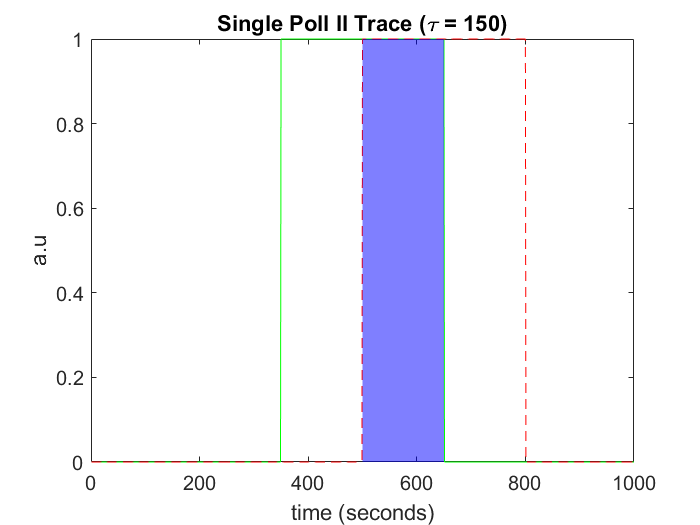


figure();
plot(1:total_len, fig1, 'g')
hold on
plot(1:total_len, delay_half, '--r')
title('Single Poll II Trace (\tau = 150)')
xlabel('time (seconds)')
ylabel('a.u')
a = area([500,650], [1,1]);
a.FaceColor = 'blue';
a.FaceAlpha = 0.5;
a.EdgeAlpha = 0;

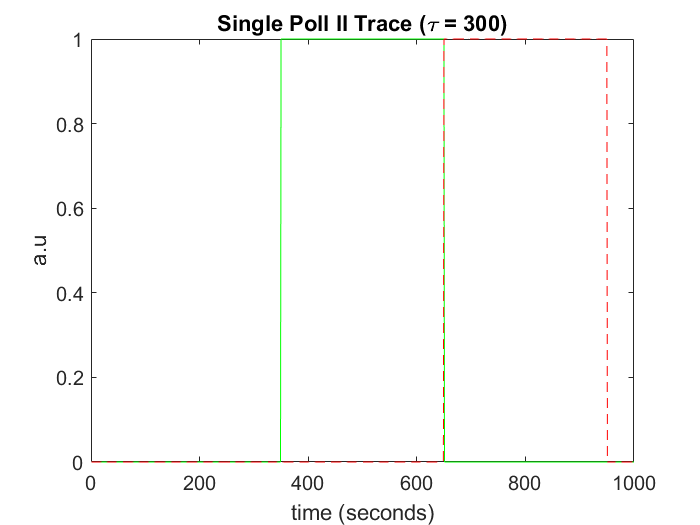


figure();
plot(1:total_len, fig1, 'g')
hold on
plot(1:total_len, delay_full, '--r')
title('Single Poll II Trace (\tau = 300)')
xlabel('time (seconds)')
ylabel('a.u')

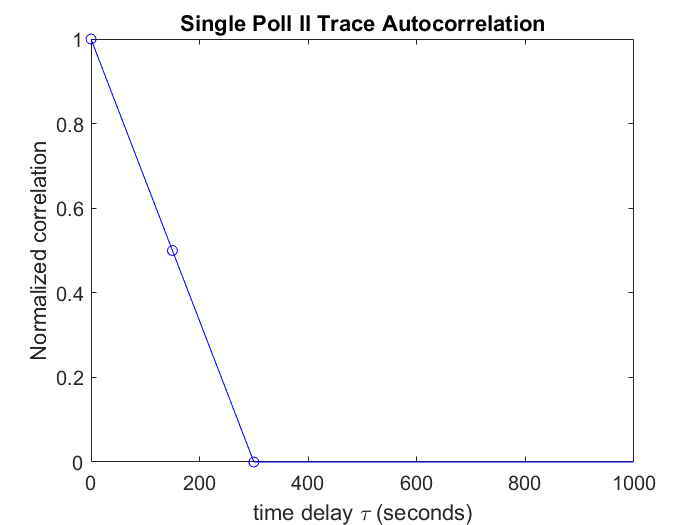


figure();
plot(0:(total_len - 1), corr, 'b');
hold on
plot([0,150,300], [1,0.5,0], 'ob')
title('Single Poll II Trace Autocorrelation')
xlabel('time delay \tau (seconds)')
ylabel('Normalized correlation')

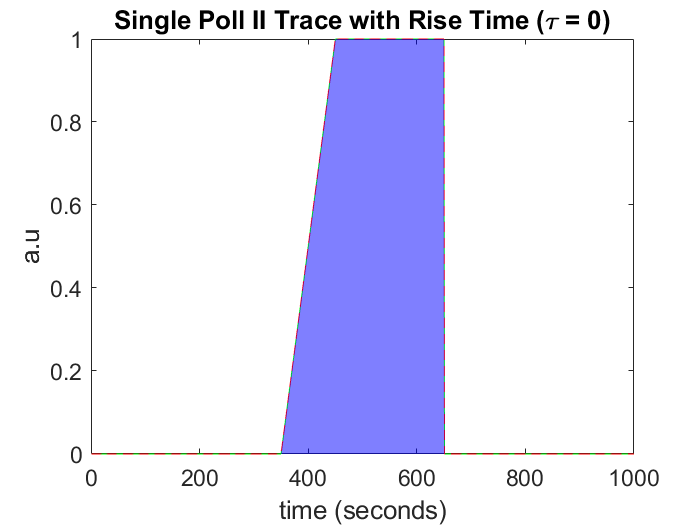

% creates single polymerase plots with rise time

elong_time = 300;
rise_time = 100;
poll_start = 350;
total_len = 1000;

fig1 = zeros(1,total_len);
fig1(1,poll_start:poll_start + rise_time) = (0:rise_time) / rise_time;
fig1(1,poll_start+rise_time:poll_start + elong_time) = 1;

delay0 = fig1;
delay_half = zeros(1, total_len);
delay_half(1,poll_start + elong_time / 2 ...
    :poll_start + elong_time / 2 + rise_time) ...
    = (0:rise_time) / rise_time;
delay_half(1,poll_start + elong_time / 2 + rise_time ...
    :poll_start + 3 * elong_time / 2) ...
    = 1;

delay_full = zeros(1, total_len);
delay_full(1, poll_start + elong_time:poll_start + elong_time + rise_time) = ...
    (0:rise_time) / rise_time;
delay_full(1, poll_start + elong_time + rise_time:poll_start + 2*elong_time) = 1;

corr = zeros(1, total_len);
for i=1:elong_time
    corr(i) = sum(fig1(poll_start:poll_start+elong_time) .* fig1(poll_start + i:poll_start+elong_time+i));
    corr(i) = corr(i) / sum(fig1.^2);
end

figure();
plot(1:total_len, fig1, 'g')
hold on
plot(1:total_len, delay0, '--r')
title('Single Poll II Trace with Rise Time (\tau = 0)')
xlabel('time (seconds)')
ylabel('a.u')
a = area(fig1);
a.FaceColor = 'blue';
a.FaceAlpha = 0.5;
a.EdgeAlpha = 0;

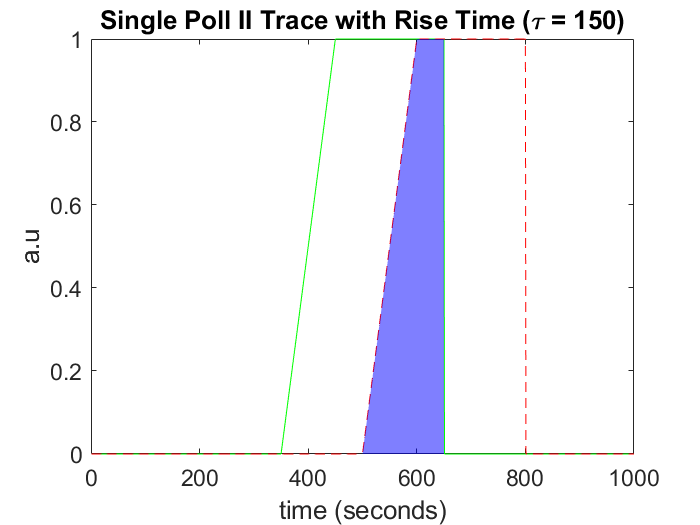


figure();
plot(1:total_len, fig1, 'g')
hold on
plot(1:total_len, delay_half, '--r')
title('Single Poll II Trace with Rise Time (\tau = 150)')
xlabel('time (seconds)')
ylabel('a.u')
a = area(delay_half(1:650));
a.FaceColor = 'blue';
a.FaceAlpha = 0.5;
a.EdgeAlpha = 0;

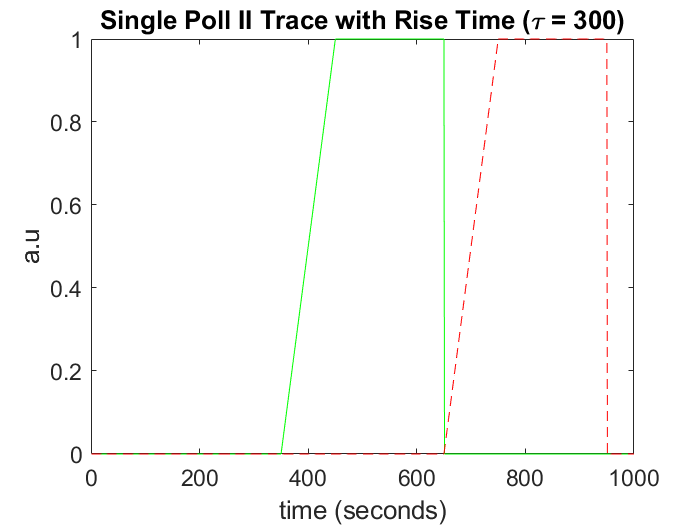


figure();
plot(1:total_len, fig1, 'g')
hold on
plot(1:total_len, delay_full, '--r')
title('Single Poll II Trace with Rise Time (\tau = 300)')
xlabel('time (seconds)')
ylabel('a.u')

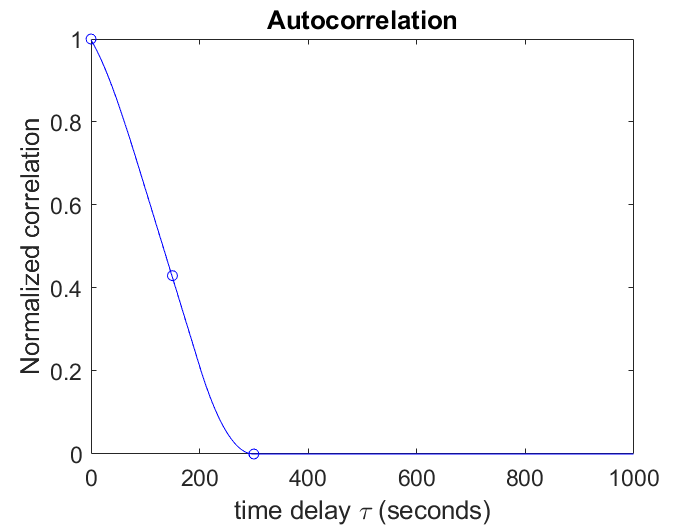


figure();
plot(0:(total_len - 1), corr, 'b');
hold on
plot([0,150,300], [1,corr(150),0], 'ob')
title('Autocorrelation')
xlabel('time delay \tau (seconds)')
ylabel('Normalized correlation')